%type1
clc
close all
clear

% Import the data
fn = 'E:\Matlab\Files\Introduction_Example\Project\ADHD_ICM_random200.xlsx'; % change this to your local path
% fn = 'ADHD_ICM_random200.xlsx';
data = readtable(fn,"VariableNamingRule",'preserve');

% Filter out the selected columns
columns_info = {'''Subject_ID''','''Gender''','''Age''','''Diagnosis'''};
data_heatmap = data(:,columns_info);
columns_ROI = {'''PCC_R''','''PCC_L''','''dorsal_ACC_R''','''dorsal_ACC_L''','''rostral_ACC_R''','''rostral_ACC_L''','''subcallosal_ACC_R''','''subcallosal_ACC_L''','''subgenual_ACC_R''','''subgenual_ACC_L'''};
data_ROI = data(:,columns_ROI);

% Isolate the control group
data_ROI_normal = data(string(data.('''Diagnosis'''))=='''NORMAL''',columns_ROI);

% Calculate the mean and standard deviation of each structure's volume for
% the control group
means = mean(table2array(data_ROI_normal));
stds = std(table2array(data_ROI_normal));

% Calculate the z score for each sample
for i = 1:length(columns_ROI)
    z = (data_ROI.(char(columns_ROI(i)))-means(i))/stds(i);
    data_heatmap.(char(columns_ROI(i))) = z; % store it in the heatmap table
end

## Customize the colorbar for the heatmap (black = 0, red = positive, blue = negative)

(This section is adapted from ChatGPT's generated code)

% Create a custom colormap
num_colors = 256;
th = 0.2; % Manually set a threshold, with positive value above which to be pure red, negative value below which to be pure blue
custom_colormap = zeros(num_colors, 3);

% Define the range for negative values (blue)
num_negative_colors = floor(num_colors/ 2);
num_below_threshold = floor(num_colors*th/2);
custom_colormap(num_negative_colors-num_below_threshold+1:num_negative_colors, 3) = linspace(1, 0, num_below_threshold); % Blue component

% Define the range for positive values (red)
num_positive_colors = ceil(num_colors / 2);
num_above_threshold = floor(num_colors*th / 2);
custom_colormap((num_colors - num_positive_colors + 1):(num_colors - num_positive_colors)+num_above_threshold, 1) = linspace(0, 1, num_above_threshold); % Red component

% Beyond threshold
custom_colormap((num_colors - num_positive_colors + 1)+num_above_threshold:num_colors, 1) = ones(1,ceil(num_positive_colors*(1-th)));
custom_colormap(1:ceil(num_negative_colors*(1-th)), 3) = ones(1,ceil(num_negative_colors*(1-th)));

## **Test1**

% Statistical Test
fc1 = 'E:\Matlab\Files\Introduction_Example\Project\Part5\Statistic_1.xlsx'; 
data2 = readtable(fc1,"VariableNamingRule",'preserve');
% columns_info2 = {'Object','Volume_mm3','Min','Max','Mean','Std'};
% Compute 
volume = data2.Volume_mm3;
volume = volume';
% for i = 1:length(columns_ROI)
z2 = (volume - means) ./ stds;

## Barcode

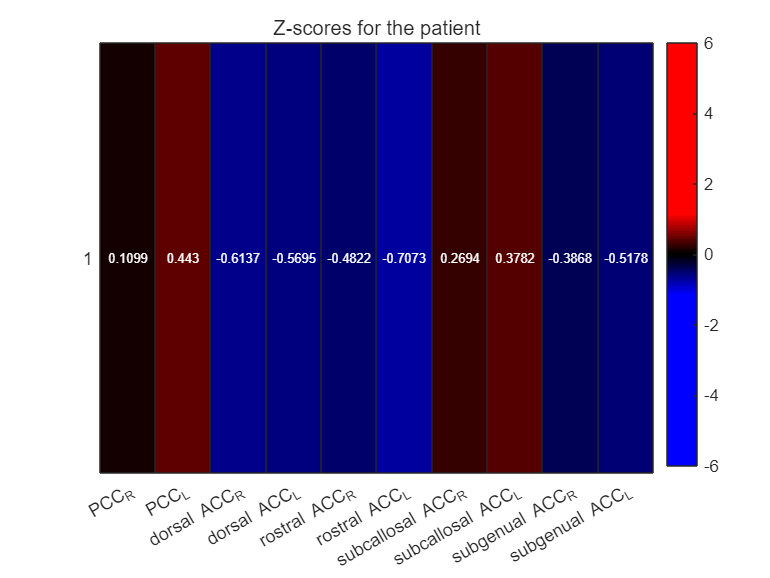

% xvalues= erase(columns_ROI,"'");
xvalues = ["PCC_R","PCC_L","dorsal ACC_R","dorsal ACC_L","rostral ACC_R","rostral ACC_L","subcallosal ACC_R","subcallosal ACC_L","subgenual ACC_R","subgenual ACC_L"];
% Create barcode for the patient
figure;
h1 = heatmap(xvalues, 1, z2, 'Colormap', colormap(custom_colormap));
title('Z-scores for the patient');
colorbar;
caxis([-6 6]);